## Linear Regression

A linear regression filter learns by adjusting weights.

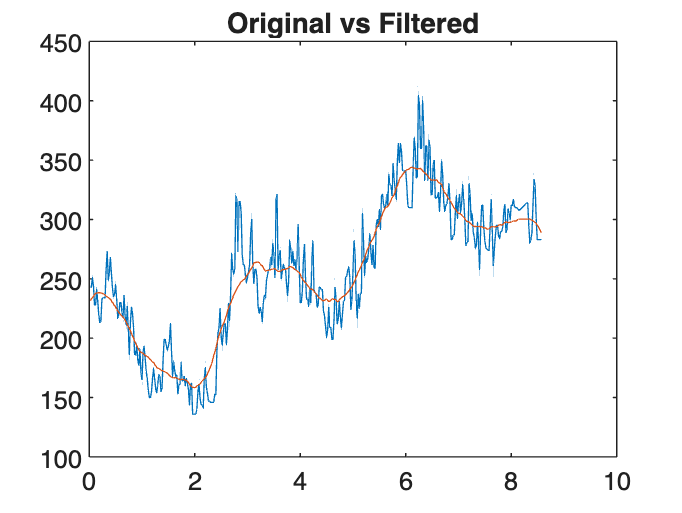

file = readmatrix("./input.csv");
time = file(:,1);
measurements = file(:,2);
bufferSize = 44;

[outputs, weights, initialStates] = linearRegressionFilter( ...
    measurements, ...
    bufferSize ...
);

plot(time, measurements, time, outputs);
title('Original vs Filtered');

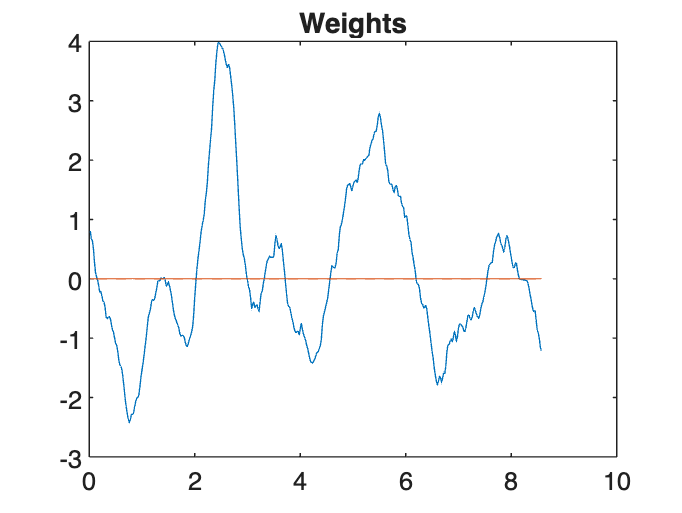


plot(weights);
title('Weights');

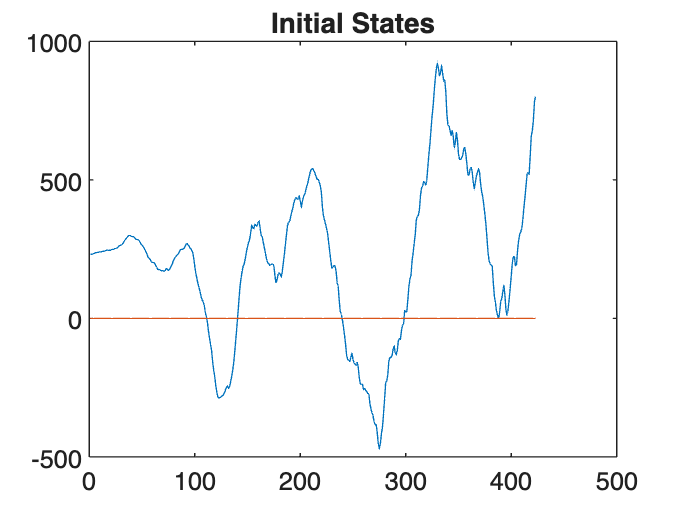


plot(initialStates);
title('Initial States');

function [ ...
    outputs, ...
    weights, ...
    initialStates ...
] = linearRegressionFilter( ...
    inputs, ...
    bufferSize ...
)
  weights = zeros(length(inputs), bufferSize);
  initialStates = zeros(length(inputs), bufferSize);
  half = floor(bufferSize / 2);
  outputs = zeros(1, length(inputs));

  for n = 1:length(inputs)
    % Sample next and previous samples around this sample
    startIndex = max(1, n - half);
    endIndex = min(length(inputs), n + half);
    x = (startIndex:endIndex)';
    y = inputs(startIndex:endIndex);
    xMean = mean(x);
    yMean = mean(y);

    % Tune contribution of input to output
    weight = ...
        sum((x - xMean) .* (y - yMean)) / ...
        sum((x - xMean) .^ 2);

    weights(n) = weight;

    % Tune initial state
    initialState = yMean - weight * xMean;
    initialStates(n) = initialState;

    % Predict
    outputs(n) = weight * n + initialState;
  end
end
